**制御対象**

A=[0 1 0;0 0 1;-2 -3 -1],B=[0;0;1],C=[2 1 1]

A =      0     1     0
     0     0     1
    -2    -3    -1


B =      0
     0
     1


C =      2     1     1


可制御性行列Ucとそのランク

Uc=[B,A*B,A^2*B], rank(Uc)

Uc =      0     0     1
     0     1    -1
     1    -1    -2


ans = 3

可観測性行列Uoとそのランク

Uo=[C;C*A;C*A^2], rank(Uo)

Uo =      2     1     1
    -2    -1     0
     0    -2    -1


ans = 3

システムの固有値（極）

eig(A)

ans =   -0.7152 + 0.0000i
  -0.1424 + 1.6661i
  -0.1424 - 1.6661i


インパルス応答

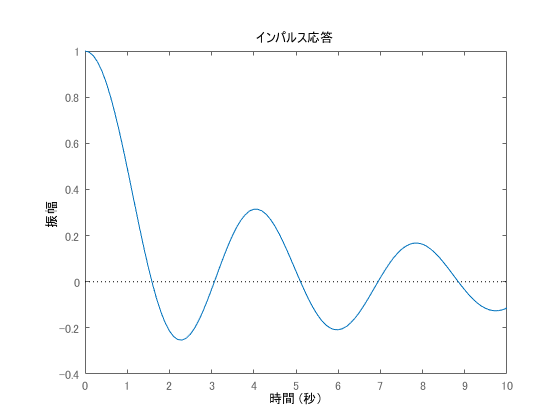

sys0 = ss(A,B,C,0);
impulse(sys0,10)

**極配置**

p1 =-8.88

p1 = -8.8800

p2 = -10.6

p2 = -10.6000

p3 = -35.6

p3 = -35.6000

p = [p1,p2,p3];
K1 = place(A,B,p)

K1 = 	1.0e+03 *

    3.3490    0.7846    0.0541


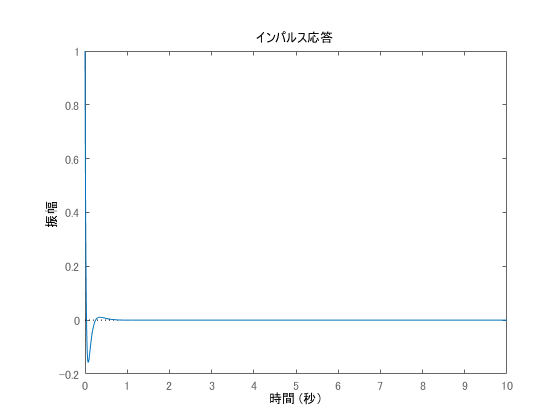

sys1 = ss(A-B*K1,B,C,0);
impulse(sys1,10)

**最適レギュレータ**

Q = 10*eye(3);
R = 4.1;
K2 = lqr(sys0,Q,R)

K2 =     0.5375    1.5096    1.5413


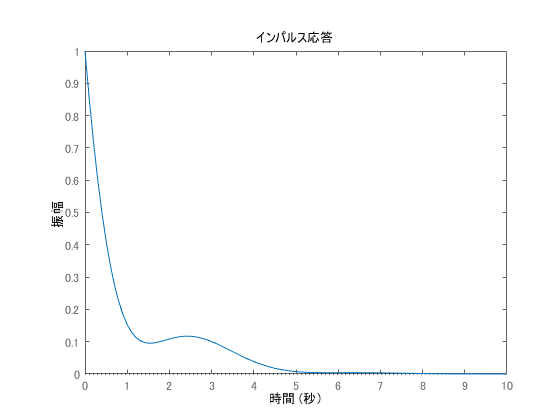

sys2 = ss(A-B*K2,B,C,0);
impulse(sys2,10)